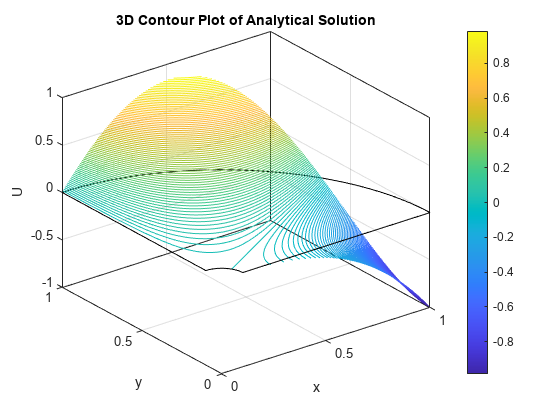

%%%% HW 1

clear; close all;
% Parameters
a = 0.1;
R = 1;
th_final = pi/2;
b = a^6;

N = 100;

% Function for U(r, th)
U = @(r, th) - (r.^3 + b*r.^(-3)) / (1 + b) .* cos(3*th);

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);

r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);

x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);

U_mesh = U(r_mesh, th_mesh);

figure
contour3(x_coor, y_coor, U_mesh, 151)
hold on
plot3(zeros(N, 1), linspace(a, R, N), zeros(N, 1), 'k')
plot3(linspace(a, R, N), zeros(N, 1), zeros(N, 1), 'k')
plot3(a*cos(th_range), a*sin(th_range), zeros(N, 1), 'k')
plot3(R*cos(th_range), R*sin(th_range), zeros(N, 1), 'k')
title('3D Contour Plot of Analytical Solution')
xlabel('x')
ylabel('y')
zlabel('U')
colorbar

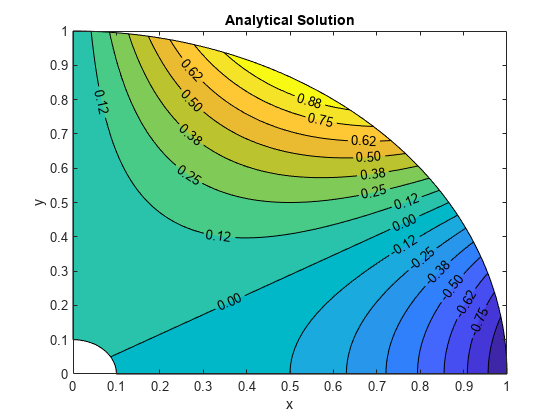


%exportgraphics(gcf, 'ContourPlot.png', 'Resolution',300)

figure
contourf(x_coor, y_coor, U_mesh, 15, "ShowText","on", "LabelFormat","%0.2f")
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Analytical Solution')
xlabel('x')
ylabel('y')

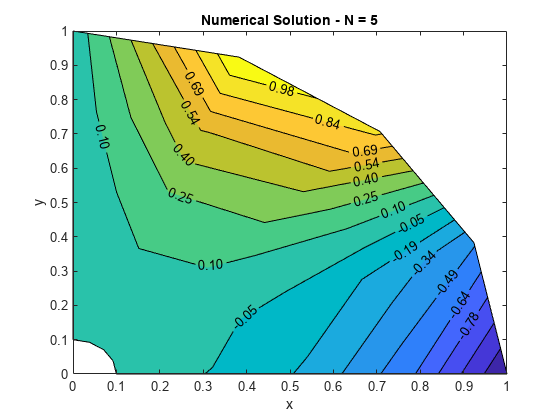

%exportgraphics(gcf, 'IsolinePlot.png', 'Resolution',300)


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% N = 5
N = 5;

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);
r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);
x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);
X_vector = readmatrix("5.txt");

X_mesh = reshape(X_vector, [N, N]);
X_mesh = -X_mesh';

figure
contourf(x_coor, y_coor, X_mesh, 15, "ShowText","on", "LabelFormat","%0.2f")
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Numerical Solution - N = 5')
xlabel('x')
ylabel('y')

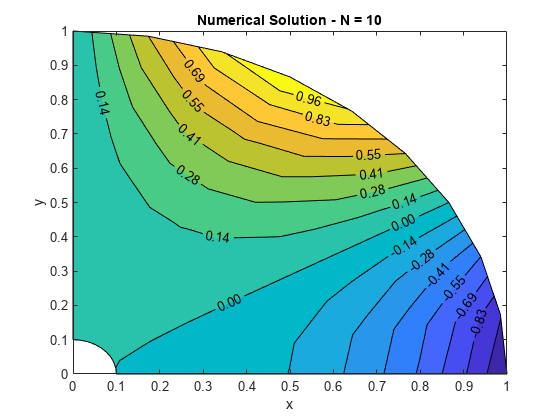

%exportgraphics(gcf, 'IsolinePlot.png', 'Resolution',300)

%%%% Error
error_mesh = abs(X_mesh - U(r_mesh, th_mesh));

%Setting colorbar limits
bottom = 0;
top  = max(max(error_mesh));

error_fig = figure;
set(error_fig, 'Position', [100, 100, 1400, 400])
subplot(1, 3, 1)
contourf(x_coor, y_coor, error_mesh, 7, "LabelFormat","%0.2f")
colormap(flipud(hot))
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Absoute Error - N = 5')
axis square;
xlabel('x')
ylabel('y')
clim manual
clim([bottom top]);
%exportgraphics(gcf, 'IsolinePlot.png', 'Resolution',300)


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% N = 10
N = 10;

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);
r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);
x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);
X_vector = readmatrix("10.txt");

X_mesh = reshape(X_vector, [N, N]);
X_mesh = -X_mesh';

figure
contourf(x_coor, y_coor, X_mesh, 15, "ShowText","on", "LabelFormat","%0.2f")
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Numerical Solution - N = 10')
xlabel('x')
ylabel('y')

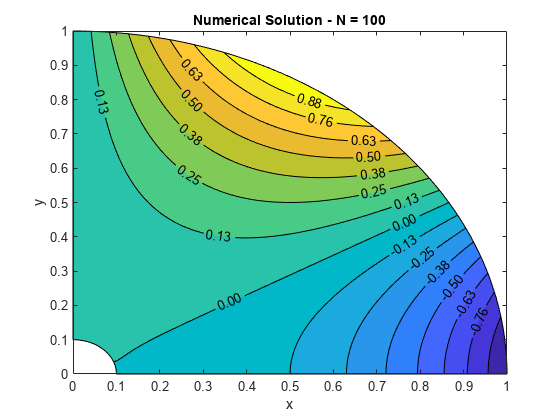

%exportgraphics(gcf, 'IsolinePlot.png', 'Resolution',300)

%%%% Error
error_mesh = abs(X_mesh - U(r_mesh, th_mesh));
figure(error_fig)
subplot(1, 3, 2)
contourf(x_coor, y_coor, error_mesh, 7, "LabelFormat","%0.2f")
colormap(flipud(hot))
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Absoute Error - N = 10')
axis square;
xlabel('x')
ylabel('y')
clim manual
clim([bottom top]);
secondPos = get(gca, 'Position');
%exportgraphics(gcf, 'IsolinePlot.png', 'Resolution',300)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% N = 120
N = 100;

% Ranges for independent variables
r_range = linspace(a, R, N);
th_range = linspace(0, th_final, N);
r_mesh = repmat(r_range, N, 1);
th_mesh = repmat(th_range', 1, N);
x_coor = r_mesh .* cos(th_mesh);
y_coor = r_mesh .* sin(th_mesh);
X_vector = readmatrix("100.txt");

X_mesh = reshape(X_vector, [N, N]);
X_mesh = -X_mesh';

figure
contourf(x_coor, y_coor, X_mesh, 15, "ShowText","on", "LabelFormat","%0.2f")
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Numerical Solution - N = 100')
xlabel('x')
ylabel('y')

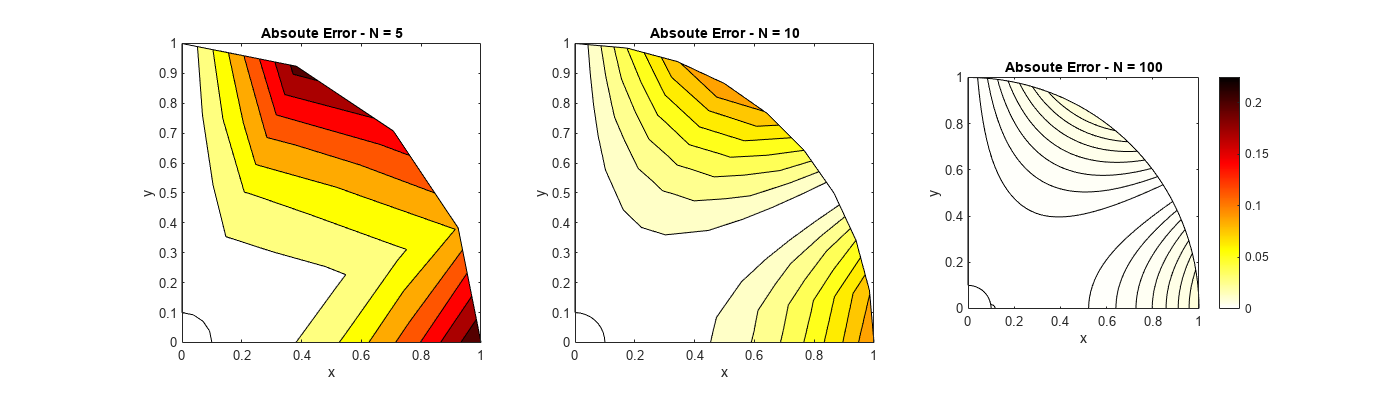

%exportgraphics(gcf, 'IsolinePlot.png', 'Resolution',300)

%%%% Error
error_mesh = abs(X_mesh - U(r_mesh, th_mesh));
figure(error_fig)
subplot(1, 3, 3)
contourf(x_coor, y_coor, error_mesh, 7, "LabelFormat","%0.2f")
colormap(flipud(hot))
colorbar
hold on
plot(zeros(N, 1), linspace(a, R, N), 'k')
plot(linspace(a, R, N), zeros(N, 1), 'k')
plot(a*cos(th_range), a*sin(th_range), 'k')
plot(R*cos(th_range), R*sin(th_range), 'k')
title('Absoute Error - N = 100')
axis square;
xlabel('x')
ylabel('y')
clim manual
clim([bottom top]);


%exportgraphics(gcf, 'IsolinePlot.png', 'Resolution',300)